# radial profiles of HI and H2

## load important things

%loadFofSub
subsInfo = illustris.infrastructure.build_sub_fof_connection(subs,fofs);
massThresh=1e9;
satMask=illustris.infrastructure.generateMask('subs',subs','fofs',fofs,'mass',massThresh,'snap',99,'sats');

## load HI H2 values by components

load('C:\Users\eladz\Documents\workProjects\matlab_scripts\IllustrisTNG\matFiles\hih2Catalog_snp99_TNG100.mat')


## build stellar mass - HI mass relationship

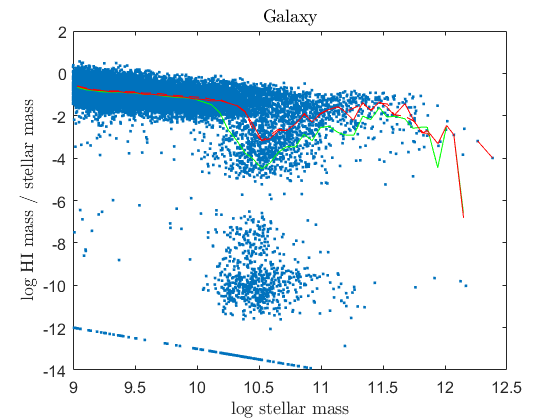


mmask=hih2Struct.galMask & hih2Struct.Gal.GalHIMass(1,:)>0;
galH_star=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
    log10(hih2Struct.Gal.GalHIMass(1,mmask)./hih2Struct.galMass(mmask)),'nb',50);

mmask=hih2Struct.galMask & hih2Struct.Gal.GalHIMass(1,:)>0 & subsInfo.isCentral;
galH_starC=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
    log10(hih2Struct.Gal.GalHIMass(1,mmask)./hih2Struct.galMass(mmask)),'nb',50);

figure
smass=hih2Struct.galMass(hih2Struct.galMask);
hMass=hih2Struct.Gal.GalHIMass(1,hih2Struct.galMask);
hMass(hMass==0)=1e-3;
plot(log10(smass),log10(hMass./smass),'.');
hold on;
plot(galH_star.xMean,galH_star.yMean,'g')
plot(galH_star.xMedian,galH_star.yMedian,'r')
plot(galH_starC.xMedian,galH_starC.yMedian,'r--')
xlabelmine('log stellar mass');
ylabelmine(' log HI mass / stellar mass');
titlemine('Galaxy');
set(gca,'fontsize',12)

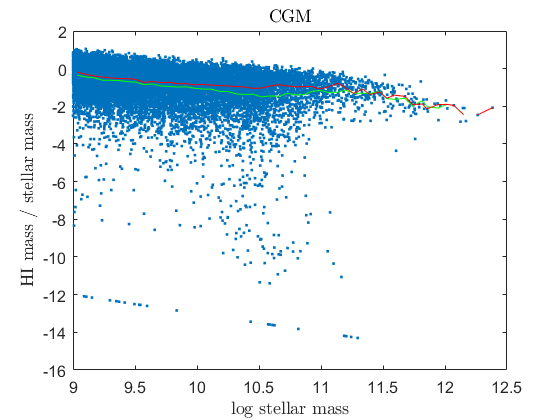



mmask=hih2Struct.galMask & hih2Struct.CGMall.CGMallHIMass(1,:)>0;
cgmH_star=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
    log10(hih2Struct.CGMall.CGMallHIMass(1,mmask)./hih2Struct.galMass(mmask)),'nb',50);

figure
smass=hih2Struct.galMass(hih2Struct.galMask);
hMass=hih2Struct.CGMall.CGMallHIMass(1,hih2Struct.galMask);
hMass(hMass==0)=1e-3;
plot(log10(smass),log10(hMass./smass),'.');
hold on;
plot(cgmH_star.xMean,cgmH_star.yMean,'g')
plot(cgmH_star.xMedian,cgmH_star.yMedian,'r')
xlabelmine('log stellar mass');
ylabelmine('HI mass / stellar mass');
titlemine('CGM');
set(gca,'fontsize',12)

## build H2 vs. stellar mass relationship

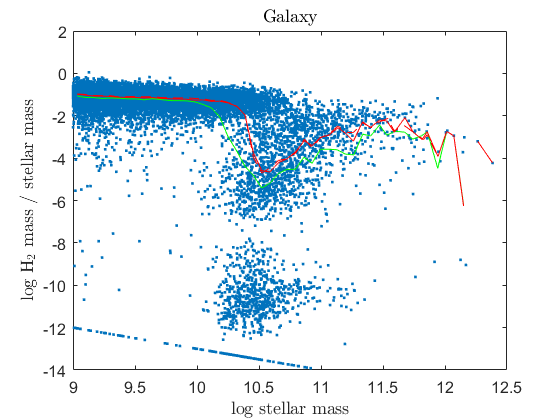

mmask=hih2Struct.galMask & hih2Struct.Gal.GalH2Mass(1,:)>0;
galH_star=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
    log10(hih2Struct.Gal.GalH2Mass(1,mmask)./hih2Struct.galMass(mmask)),'nb',50);

mmask=hih2Struct.galMask & hih2Struct.Gal.GalH2Mass(1,:)>0 & subsInfo.isCentral;
galH_starC=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
    log10(hih2Struct.Gal.GalH2Mass(1,mmask)./hih2Struct.galMass(mmask)),'nb',50);

figure
smass=hih2Struct.galMass(hih2Struct.galMask);
hMass=hih2Struct.Gal.GalH2Mass(1,hih2Struct.galMask);
hMass(hMass==0)=1e-3;
plot(log10(smass),log10(hMass./smass),'.');
hold on;
plot(galH_star.xMean,galH_star.yMean,'g')
plot(galH_star.xMedian,galH_star.yMedian,'r')
plot(galH_starC.xMedian,galH_starC.yMedian,'r--')
xlabelmine('log stellar mass');
ylabelmine(' log $\mathrm{H_2}$ mass / stellar mass');
titlemine('Galaxy');
set(gca,'fontsize',12)

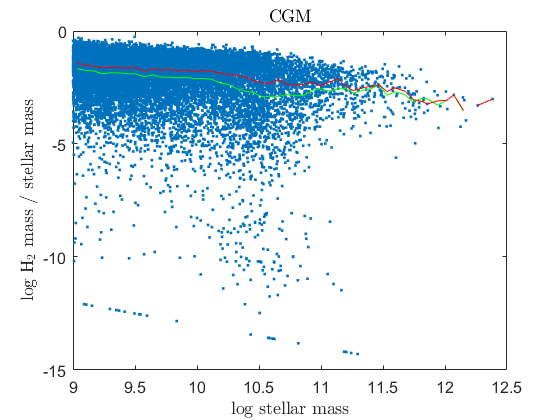



mmask=hih2Struct.galMask & hih2Struct.CGMall.CGMallH2Mass(1,:)>0;
cgmH_star=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
    log10(hih2Struct.CGMall.CGMallH2Mass(1,mmask)./hih2Struct.galMass(mmask)),'nb',50);

figure
smass=hih2Struct.galMass(hih2Struct.galMask);
hMass=hih2Struct.CGMall.CGMallH2Mass(1,hih2Struct.galMask);
hMass(hMass==0)=1e-3;
plot(log10(smass),log10(hMass./smass),'.');
hold on;
plot(cgmH_star.xMean,cgmH_star.yMean,'g')
plot(cgmH_star.xMedian,cgmH_star.yMedian,'r')
xlabelmine('log stellar mass');
ylabelmine('log $\mathrm{H_2}$ mass / stellar mass');
titlemine('CGM');
set(gca,'fontsize',12)

## explore the model dependencs of the hydrogen to stellar mass relation

for k=1:3
    
    % gal
    mmask=hih2Struct.galMask & hih2Struct.Gal.GalHIMass(k,:)>0;
    galHI_star(k)=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
        log10(hih2Struct.Gal.GalHIMass(k,mmask)./hih2Struct.galMass(mmask)),'nb',50);
    
    mmask=hih2Struct.galMask & hih2Struct.Gal.GalH2Mass(k,:)>0;
    galH2_star(k)=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
        log10(hih2Struct.Gal.GalH2Mass(k,mmask)./hih2Struct.galMass(mmask)),'nb',50);
    
    % gal centrals
    mmask=hih2Struct.galMask & hih2Struct.Gal.GalHIMass(k,:)>0 & subsInfo.isCentral;
    galHI_starC(k)=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
        log10(hih2Struct.Gal.GalHIMass(k,mmask)./hih2Struct.galMass(mmask)),'nb',50);
    mmask=hih2Struct.galMask & hih2Struct.Gal.GalH2Mass(k,:)>0 & subsInfo.isCentral;
    galH2_starC(k)=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
        log10(hih2Struct.Gal.GalH2Mass(k,mmask)./hih2Struct.galMass(mmask)),'nb',50);
    
    
    % cgm
    mmask=hih2Struct.galMask & hih2Struct.CGMall.CGMallHIMass(k,:)>0;
    cgmHI_star(k)=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
        log10(hih2Struct.CGMall.CGMallHIMass(k,mmask)./hih2Struct.galMass(mmask)),'nb',50);
    mmask=hih2Struct.galMask & hih2Struct.CGMall.CGMallH2Mass(k,:)>0;
    cgmH2_star(k)=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
        log10(hih2Struct.CGMall.CGMallH2Mass(k,mmask)./hih2Struct.galMass(mmask)),'nb',50);
    
    % cgm centrals
    mmask=hih2Struct.galMask & hih2Struct.CGMall.CGMallHIMass(k,:)>0 & subsInfo.isCentral;
    cgmHI_starC(k)=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
        log10(hih2Struct.CGMall.CGMallHIMass(k,mmask)./hih2Struct.galMass(mmask)),'nb',50);
    mmask=hih2Struct.galMask & hih2Struct.CGMall.CGMallH2Mass(k,:)>0 & subsInfo.isCentral;
    cgmH2_starC(k)=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
        log10(hih2Struct.CGMall.CGMallH2Mass(k,mmask)./hih2Struct.galMass(mmask)),'nb',50);
    
end


## perliminaries


colors=brewermap(8,'Set1');
cind=[2 5 3 1];
htag={'11-12','12-13','13-14','14-15'};
mtag={'9-10','10-11','11-12'};
modelTag=hih2Struct.Gal.Hmodel;

## plot model dependence

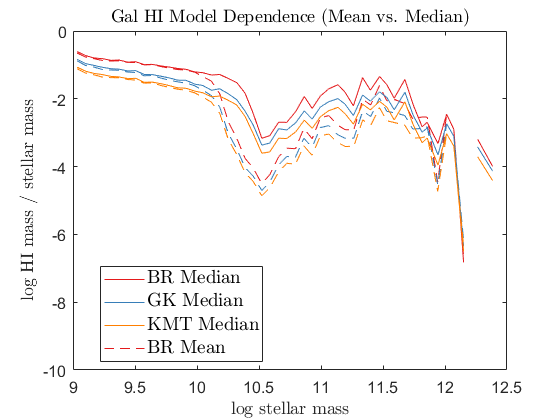


% gal HI

figure
cc=[1,2,5];
h=[];
for k=1:3
    h(end+1)=plot(galHI_star(k).xMedian,galHI_star(k).yMedian,'color',colors(cc(k),:),...
        'DisplayName',[modelTag{k} ' Median']);
    if k==1; hold on; end
    h(end+1)=plot(galHI_star(k).xMean,galHI_star(k).yMean,'--','color',colors(cc(k),:),...
        'DisplayName',[modelTag{k} ' Mean']);
end
ylim([-10 0])
legend(h([1:2:6 2]),'FontSize',14,'Interpreter','latex','Location','best');
xlabelmine('log stellar mass');
ylabelmine('log $\mathrm{HI}$ mass / stellar mass');
titlemine('Gal HI Model Dependence (Mean vs. Median)');
set(gca,'fontsize',12)

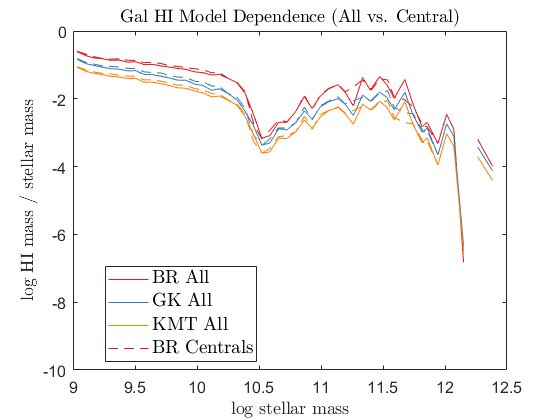


figure
cc=[1,2,5];
h=[];
for k=1:3
    h(end+1)=plot(galHI_star(k).xMedian,galHI_star(k).yMedian,'color',colors(cc(k),:),...
        'DisplayName',[modelTag{k} ' All']);
    if k==1; hold on; end
    h(end+1)=plot(galHI_starC(k).xMedian,galHI_starC(k).yMedian,'--','color',colors(cc(k),:),...
        'DisplayName',[modelTag{k} ' Centrals']);
end
ylim([-10 0])
legend(h([1:2:6 2]),'FontSize',14,'Interpreter','latex','Location','best');
xlabelmine('log stellar mass');
ylabelmine('log $\mathrm{HI}$ mass / stellar mass');
titlemine('Gal HI Model Dependence (All vs. Central)');
set(gca,'fontsize',12)

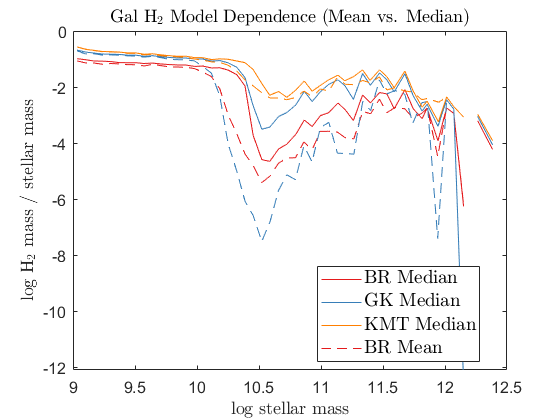


% gal H2
figure
cc=[1,2,5];
h=[];
for k=1:3
    h(end+1)=plot(galH2_star(k).xMedian,galH2_star(k).yMedian,'color',colors(cc(k),:),...
        'DisplayName',[modelTag{k} ' Median']);
    if k==1; hold on; end
    h(end+1)=plot(galH2_star(k).xMean,galH2_star(k).yMean,'--','color',colors(cc(k),:),...
        'DisplayName',[modelTag{k} ' Mean']);
end
ylim([-10 0])
legend(h([1:2:6 2]),'FontSize',14,'Interpreter','latex','Location','best');
xlabelmine('log stellar mass');
ylabelmine('log $\mathrm{H_2}$ mass / stellar mass');
titlemine('Gal $\mathrm{H_2}$ Model Dependence (Mean vs. Median)');
set(gca,'fontsize',12)

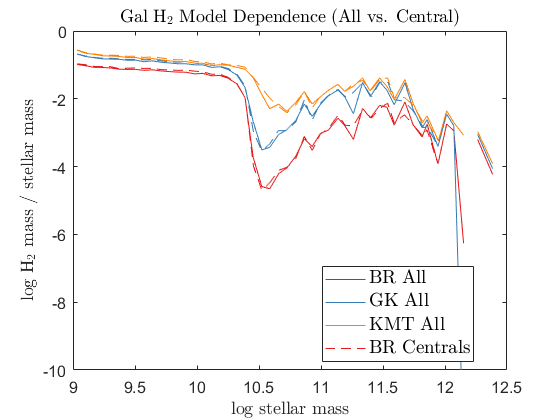


figure
cc=[1,2,5];
h=[];
for k=1:3
    h(end+1)=plot(galH2_star(k).xMedian,galH2_star(k).yMedian,'color',colors(cc(k),:),...
        'DisplayName',[modelTag{k} ' All']);
    if k==1; hold on; end
    h(end+1)=plot(galH2_starC(k).xMedian,galH2_starC(k).yMedian,'--','color',colors(cc(k),:),...
        'DisplayName',[modelTag{k} ' Centrals']);
end
ylim([-10 0])
legend(h([1:2:6 2]),'FontSize',14,'Interpreter','latex','Location','best');
xlabelmine('log stellar mass');
ylabelmine('log $\mathrm{H_2}$ mass / stellar mass');
titlemine('Gal $\mathrm{H_2}$ Model Dependence (All vs. Central)');
set(gca,'fontsize',12)

## now CGM

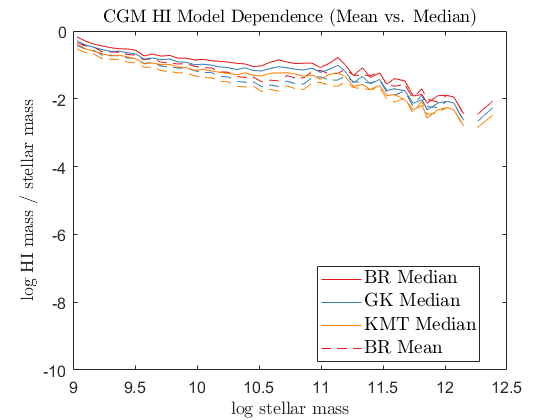

% gal HI

figure
cc=[1,2,5];
h=[];
for k=1:3
    h(end+1)=plot(cgmHI_star(k).xMedian,cgmHI_star(k).yMedian,'color',colors(cc(k),:),...
        'DisplayName',[modelTag{k} ' Median']);
    if k==1; hold on; end
    h(end+1)=plot(cgmHI_star(k).xMean,cgmHI_star(k).yMean,'--','color',colors(cc(k),:),...
        'DisplayName',[modelTag{k} ' Mean']);
end
ylim([-10 0])
legend(h([1:2:6 2]),'FontSize',14,'Interpreter','latex','Location','best');
xlabelmine('log stellar mass');
ylabelmine('log $\mathrm{HI}$ mass / stellar mass');
titlemine('CGM HI Model Dependence (Mean vs. Median)');
set(gca,'fontsize',12)

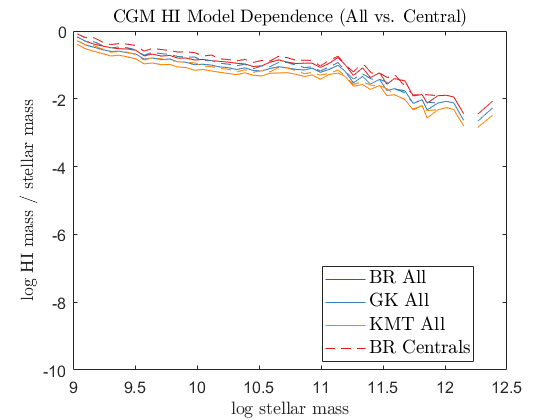


figure
cc=[1,2,5];
h=[];
for k=1:3
    h(end+1)=plot(cgmHI_star(k).xMedian,cgmHI_star(k).yMedian,'color',colors(cc(k),:),...
        'DisplayName',[modelTag{k} ' All']);
    if k==1; hold on; end
    h(end+1)=plot(cgmHI_starC(k).xMedian,cgmHI_starC(k).yMedian,'--','color',colors(cc(k),:),...
        'DisplayName',[modelTag{k} ' Centrals']);
end
ylim([-10 0])
legend(h([1:2:6 2]),'FontSize',14,'Interpreter','latex','Location','best');
xlabelmine('log stellar mass');
ylabelmine('log $\mathrm{HI}$ mass / stellar mass');
titlemine('CGM HI Model Dependence (All vs. Central)');
set(gca,'fontsize',12)

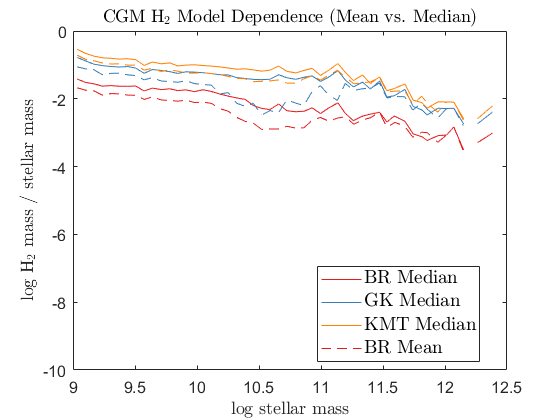


% gal H2
figure
cc=[1,2,5];
h=[];
for k=1:3
    h(end+1)=plot(cgmH2_star(k).xMedian,cgmH2_star(k).yMedian,'color',colors(cc(k),:),...
        'DisplayName',[modelTag{k} ' Median']);
    if k==1; hold on; end
    h(end+1)=plot(cgmH2_star(k).xMean,cgmH2_star(k).yMean,'--','color',colors(cc(k),:),...
        'DisplayName',[modelTag{k} ' Mean']);
end
ylim([-10 0])
legend(h([1:2:6 2]),'FontSize',14,'Interpreter','latex','Location','best');
xlabelmine('log stellar mass');
ylabelmine('log $\mathrm{H_2}$ mass / stellar mass');
titlemine('CGM $\mathrm{H_2}$ Model Dependence (Mean vs. Median)');
set(gca,'fontsize',12)

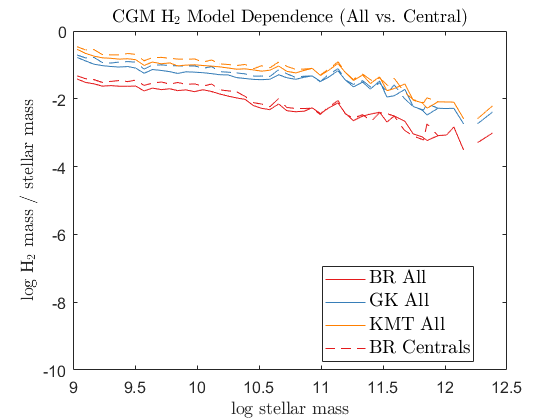


figure
cc=[1,2,5];
h=[];
for k=1:3
    h(end+1)=plot(cgmH2_star(k).xMedian,cgmH2_star(k).yMedian,'color',colors(cc(k),:),...
        'DisplayName',[modelTag{k} ' All']);
    if k==1; hold on; end
    h(end+1)=plot(cgmH2_starC(k).xMedian,cgmH2_starC(k).yMedian,'--','color',colors(cc(k),:),...
        'DisplayName',[modelTag{k} ' Centrals']);
end

legend(h([1:2:6 2]),'FontSize',14,'Interpreter','latex','Location','best');
xlabelmine('log stellar mass');
ylabelmine('log $\mathrm{H_2}$ mass / stellar mass');
titlemine('CGM $\mathrm{H_2}$ Model Dependence (All vs. Central)');
set(gca,'fontsize',12)
ylim([-10 0])

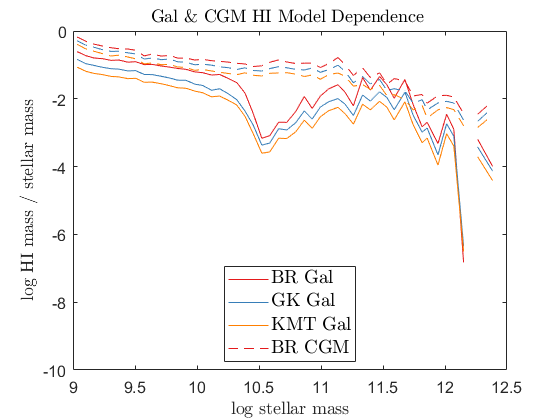



%% plot gal and CGM together 
figure
cc=[1,2,5];
h=[];
for k=1:3
    h(end+1)=plot(galHI_star(k).xMedian,galHI_star(k).yMedian,'color',colors(cc(k),:),...
        'DisplayName',[modelTag{k} ' Gal']);
    if k==1; hold on; end
    h(end+1)=plot(cgmHI_star(k).xMedian,cgmHI_star(k).yMedian,'--','color',colors(cc(k),:),...
        'DisplayName',[modelTag{k} ' CGM']);
end

legend(h([1:2:6 2]),'FontSize',14,'Interpreter','latex','Location','best');
xlabelmine('log stellar mass');
ylabelmine('log $\mathrm{HI}$ mass / stellar mass');
titlemine('Gal \& CGM $\mathrm{HI}$ Model Dependence ');
set(gca,'fontsize',12)
ylim([-10 0])

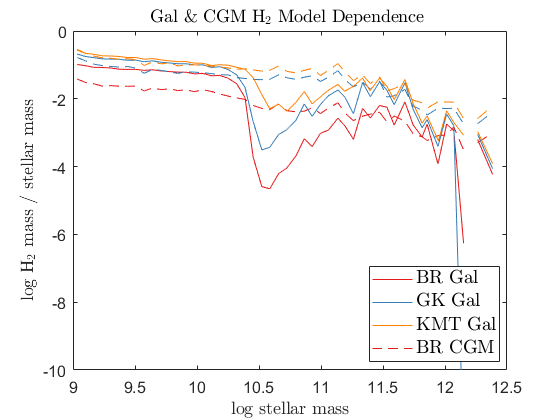


figure
cc=[1,2,5];
h=[];
for k=1:3
    h(end+1)=plot(galH2_star(k).xMedian,galH2_star(k).yMedian,'color',colors(cc(k),:),...
        'DisplayName',[modelTag{k} ' Gal']);
    if k==1; hold on; end
    h(end+1)=plot(cgmH2_star(k).xMedian,cgmH2_star(k).yMedian,'--','color',colors(cc(k),:),...
        'DisplayName',[modelTag{k} ' CGM']);
end

legend(h([1:2:6 2]),'FontSize',14,'Interpreter','latex','Location','best');
xlabelmine('log stellar mass');
ylabelmine('log $\mathrm{H_2}$ mass / stellar mass');
titlemine('Gal \& CGM $\mathrm{H_2}$ Model Dependence ');
%titlemine('CGM $\mathrm{H_2}$ Model Dependence (All vs. Central)');
set(gca,'fontsize',12)
ylim([-10 0])